# **Lab 1**

*Joel Sundin, Pablo Gonzalez Baron*

### 1. Histogram Equalization

We start by creating a histogram of the given image. We then calculate the cumulative sum of the histogram and normalizes this array so that it ranges from 0 to 1. Each pixel value and its corresponding equalized value is then mapped and the output is converted back to uint8.

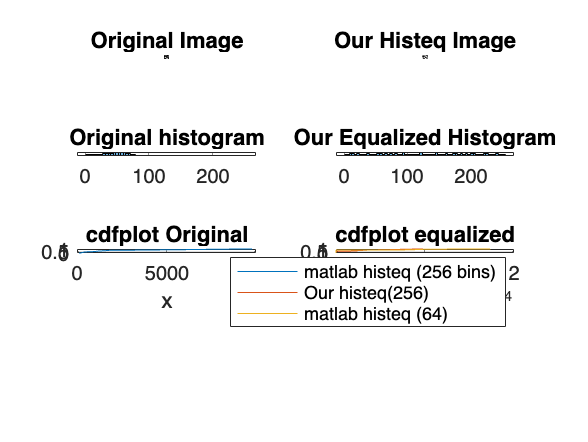

clear;

I = imread("images/greytoys.png");
my_histeq = myhisteq(I);
matlab_histeq_256_bins = histeq(I, 256);
matlab_histeq_64_bins = histeq(I);

figure
subplot(4, 2, 1)
imshow(I)
title('Original Image')

subplot(4, 2, 2)
imshow(my_histeq)
title('Our Histeq Image')

subplot(4, 2, 3)
histogram(I, 64)
title('Original histogram')

subplot(4, 2, 4)
histogram(my_histeq, 64)
title('Our Equalized Histogram')

%Original cdfplot
subplot(4, 2, 5);
cdfplot(imhist(I))
title('cdfplot Original')

%Original cdfplot
subplot(4, 2, 6);
cdfplot(imhist(matlab_histeq_256_bins))
hold on 
cdfplot(imhist(my_histeq))
hold on
cdfplot(imhist(matlab_histeq_64_bins))
legend('matlab histeq (256 bins)', 'Our histeq(256)', 'matlab histeq (64)')
title('cdfplot equalized')
hold off

function histeq = myhisteq(image)
    histogram = myhist(image);
    sum = cumsum(histogram);
    cdf = sum / sum(end);
    levels = 255;

    mapping = round((levels) * cdf);
    out = mapping(double(image) + 1);
    histeq = uint8(out);
end

function histogram = myhist(image)
    [rows, cols] = size(image);
    histogram = zeros(1, 256); % [0, 255]

    for i=1:1:rows
        for j=1:1:cols
            pixel_intensity = image(i, j);
            histogram(pixel_intensity + 1) = histogram(pixel_intensity + 1) + 1;
        end
    end
end

### 2. Global Thresholding

We create a function where we first normalize the histogram counts to get the probabilities, then we compute the cumulative sums and means, and finally we compute the between-class variance for each possible threshold.

At the end we compare our result with the **graythresh** method from MATLAB which slightly differs from our result.

Testing threshold value: 1
Testing threshold value: 2
Testing threshold value: 3
Testing threshold value: 4
Testing threshold value: 5
Testing threshold value: 6
Testing threshold value: 7
Testing threshold value: 8
Testing threshold value: 9
Testing threshold value: 10
Testing threshold value: 11
Testing threshold value: 12
Testing threshold value: 13
Testing threshold value: 14
Testing threshold value: 15
Testing threshold value: 16
Testing threshold value: 17
Testing threshold value: 18
Testing threshold value: 19
Testing threshold value: 20
Testing threshold value: 21
Testing threshold value: 22
Value for between-class variance: 132.744404
Testing threshold value: 23
Value for between-class variance: 132.744404
Testing threshold value: 24
Value for between-class variance: 132.744404
Testing threshold value: 25
Value for between-class variance: 132.744404
Testing threshold value: 26
Value for between-class variance: 132.744404
Testing threshold value: 27
Value for between-class vari

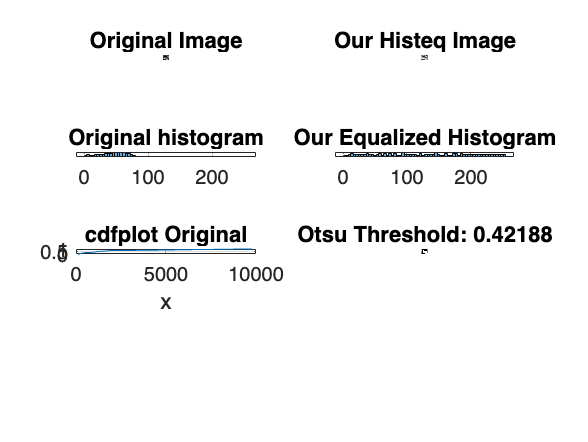

ans = 0.4219

% Read the image
I = imread('images/hand2BW.png');

function otsu_threshold = otsu_method(I)
    % Get the histogram of the image
    [counts, bin_locations] = imhist(I);
    
    % Normalize the histogram counts to get probabilities
    pixel_count = sum(counts);
    normalized_hist = counts / pixel_count;
    
    % Compute cumulative sums and means
    cumulative_sum = cumsum(normalized_hist);
    cumulative_mean = cumsum(bin_locations .* normalized_hist);
    global_mean = cumulative_mean(end);
    
    % Initialize variables
    between_class_variance = zeros(length(bin_locations), 1);
    
    % Compute between-class variance for each possible threshold
    for t = 1:length(bin_locations)
        fprintf('Testing threshold value: %d\n', t);
        if cumulative_sum(t) == 0 || cumulative_sum(t) == 1
            % Skip t values where one of the classes would be empty
            continue;
        end
        
        % Probabilities for class 0 (background) and class 1 (foreground)
        prob_class0 = cumulative_sum(t);
        prob_class1 = 1 - prob_class0;
        
        % Means for class 0 and class 1
        mean_class0 = cumulative_mean(t) / prob_class0;
        mean_class1 = (global_mean - cumulative_mean(t)) / prob_class1;
        
        % Between-class variance
        between_class_variance(t) = prob_class0 * prob_class1 * (mean_class0 - mean_class1)^2;
        fprintf('Value for between-class variance: %f\n', between_class_variance(t));
    end

    % Find the threshold that maximizes the between-class variance
    [~, otsu_threshold] = max(between_class_variance);
    
    % Display the thresholded image
    thresholded_image = I > otsu_threshold;
    imshow(thresholded_image);
    title(['Otsu Threshold: ', num2str(otsu_threshold/256)]);
end

otsu_method(I)/256

graythresh(I)

ans = 0.4196

### 3. Colour Spaces

First we apply Otsu thresholding to our image in the RGB space, by first separating the three channels and then applying the MATLAB function for Otsu thresholding on each image:

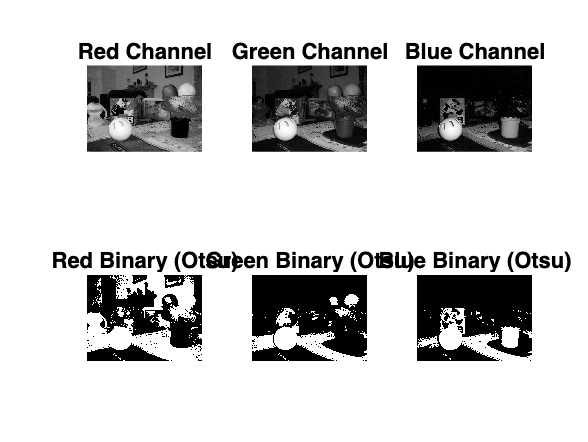

I = imread("images/toysflash.png");

function otsuThresholdingRGB(image)
    % Split the image into its three channels: Red, Green, Blue
    redChannel = image(:, :, 1);   % Red channel
    greenChannel = image(:, :, 2); % Green channel
    blueChannel = image(:, :, 3);  % Blue channel

    % Apply Otsu's thresholding to each channel
    redThreshold = graythresh(redChannel); % Otsu's threshold for red
    greenThreshold = graythresh(greenChannel); % Otsu's threshold for green
    blueThreshold = graythresh(blueChannel); % Otsu's threshold for blue

    % Convert channels to binary images using Otsu's threshold
    redBinary = imbinarize(redChannel, redThreshold);
    greenBinary = imbinarize(greenChannel, greenThreshold);
    blueBinary = imbinarize(blueChannel, blueThreshold);

    % Display the original channels and their thresholded binary images
    figure;

    % Red channel
    subplot(2, 3, 1);
    imshow(redChannel);
    title('Red Channel');
    
    subplot(2, 3, 4);
    imshow(redBinary);
    title('Red Binary (Otsu)');

    % Green channel
    subplot(2, 3, 2);
    imshow(greenChannel);
    title('Green Channel');
    
    subplot(2, 3, 5);
    imshow(greenBinary);
    title('Green Binary (Otsu)');

    % Blue channel
    subplot(2, 3, 3);
    imshow(blueChannel);
    title('Blue Channel');
    
    subplot(2, 3, 6);
    imshow(blueBinary);
    title('Blue Binary (Otsu)');
end

otsuThresholdingRGB(I)

Now, we do the exact same thing but now transforming our image to the HSV space first.

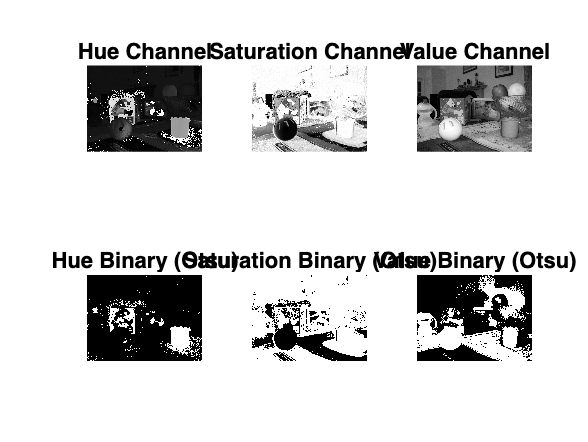

function otsuThresholdingHSV(image)
    % Convert the RGB image to HSV
    hsvImage = rgb2hsv(image);

    % Split the HSV image into its three channels: Hue, Saturation, Value
    hueChannel = hsvImage(:, :, 1);    % Hue channel
    saturationChannel = hsvImage(:, :, 2); % Saturation channel
    valueChannel = hsvImage(:, :, 3);  % Value channel

    % Apply Otsu's thresholding to each channel
    hueThreshold = graythresh(hueChannel); % Otsu's threshold for Hue
    saturationThreshold = graythresh(saturationChannel); % Otsu's threshold for Saturation
    valueThreshold = graythresh(valueChannel); % Otsu's threshold for Value

    % Convert channels to binary images using Otsu's threshold
    hueBinary = imbinarize(hueChannel, hueThreshold);
    saturationBinary = imbinarize(saturationChannel, saturationThreshold);
    valueBinary = imbinarize(valueChannel, valueThreshold);

    % Display the original channels and their thresholded binary images
    figure;

    % Hue channel
    subplot(2, 3, 1);
    imshow(hueChannel);
    title('Hue Channel');
    
    subplot(2, 3, 4);
    imshow(hueBinary);
    title('Hue Binary (Otsu)');

    % Saturation channel
    subplot(2, 3, 2);
    imshow(saturationChannel);
    title('Saturation Channel');
    
    subplot(2, 3, 5);
    imshow(saturationBinary);
    title('Saturation Binary (Otsu)');

    % Value channel
    subplot(2, 3, 3);
    imshow(valueChannel);
    title('Value Channel');
    
    subplot(2, 3, 6);
    imshow(valueBinary);
    title('Value Binary (Otsu)');
end

otsuThresholdingHSV(I)

### 4. Multispectral Images

% 4
clear;

load landsat_data.mat
disp('Include in your report the combination which best visualises the urban area, as well as the one that highlights the agricultural area.')

Include in your report the combination which best visualises the urban area, as well as the one that highlights the agricultural area.


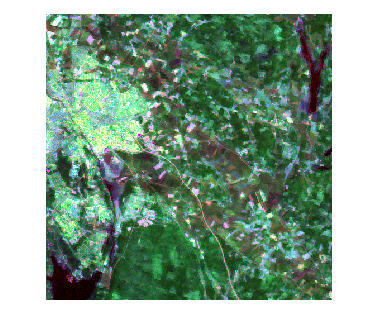

figure
imshow(landsat_data(:,:,[1,6,7]));

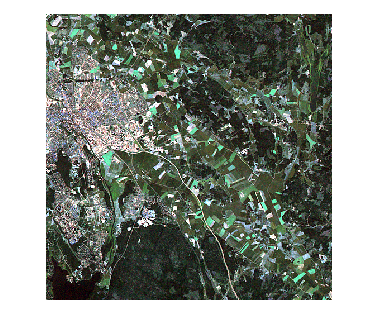

figure
imshow(landsat_data(:,:,[1,2,3]))

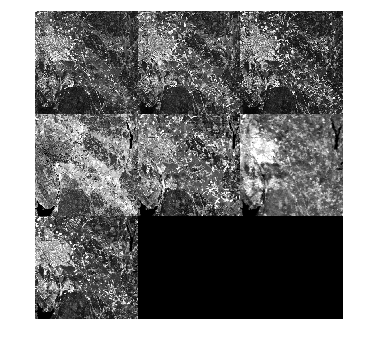

figure
montage(landsat_data)
hold off

### 5. Pixel Neighbourhoods - Mean Filter

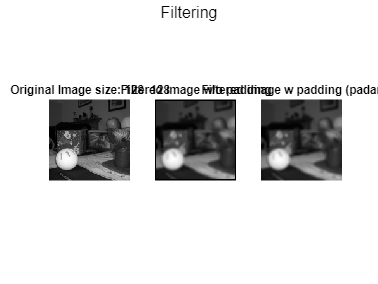

clear;

I = imread("images\toysflash.png");

I = rgb2gray(I);
I = im2double(I);
[orig_rows, orig_cols] = size(I);

%The image is cropped to a square according to the smallest axis
min_dim = min(orig_rows, orig_cols);
row_start = floor((orig_rows - min_dim) / 2) + 1;
col_start = floor((orig_cols - min_dim) / 2) + 1;

I_cropped = I(row_start:row_start + min_dim - 1, col_start:col_start + min_dim - 1);
I_resized = imresize(I_cropped, [128, 128]);

%filtering
w_size = 5;
filtered_no_padding = mean_filter_no_padding(I_resized, w_size);
filtered_padding = mean_filter_w_padding(I_resized, w_size);

figure
sgtitle('Filtering')
subplot(1, 3, 1)
imshow(I_resized)
title(['Original Image size: ', num2str(size(I_resized))])
subplot(1, 3, 2)
imshow(filtered_no_padding)
title('Filtered image w/o padding')
subplot(1, 3, 3)
imshow(filtered_padding)
title('Filtered image w padding (padarray)')

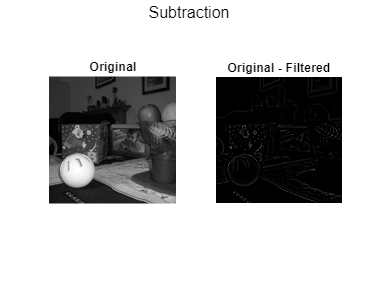


%subtraction
figure
sgtitle('Subtraction')
subplot(1, 2, 1)
imshow(I_resized)
title('Original')
subplot(1,2,2)
imshow(I_resized - filtered_padding)
title('Original - Filtered')



function I_filtered = mean_filter_no_padding(I, w_size)
    w_size = round(w_size);
    center = floor(w_size / 2);
    [rows, cols] = size(I);
    I_filtered = zeros(rows, cols);
    for i = 1:rows-w_size+1
        for j = 1:cols-w_size+1
            window = I(i:i+w_size-1, j:j+w_size-1);
            window_mean = sum(window, 'all') / w_size^2;
            I_filtered(i+center, j+center) = window_mean;
        end
    end
end

function I_filtered = mean_filter_w_padding(I, w_size)
    [rows, cols] = size(I);
    padding = floor(w_size / 2);
    I_filtered = zeros(rows, cols);
    I_padded = padarray(I, [padding, padding], 'replicate', 'both');
    for i = 1:rows
        for j = 1:cols
            window = I_padded(i:i+w_size-1, j:j+w_size-1);
            window_mean = sum(window, 'all') / w_size^2;
            I_filtered(i, j) = window_mean;
        end
    end
end

### 6. Preprocessing and Segmentation

clear;

I = imread("images\hand2BW.png");
[counts, x] = imhist(I,256)

counts =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


x =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


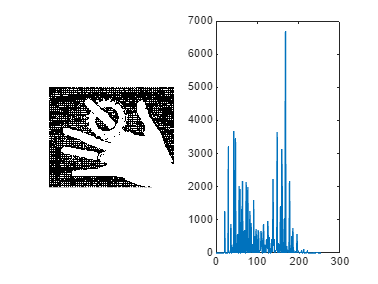

plot(x,counts);

T = otsuthresh(counts)

T = 0.4196

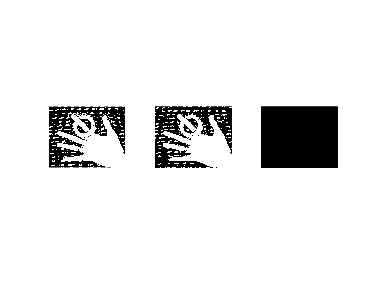

threshold = graythresh(I);
I_otsu_bin = imbinarize(I, T);
I_otsu_bin2 = imbinarize(I, threshold);
figure
subplot(1,3,1)
imshow(I_otsu_bin2)
subplot(1,3,2)
imshow(I_otsu_bin)
subplot(1,3,3)
imshow(I_otsu_bin2 - I_otsu_bin)

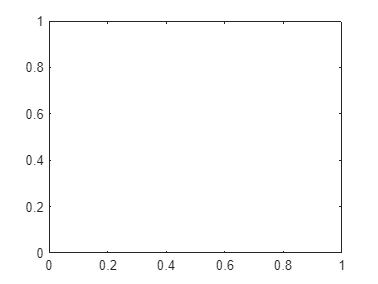

clear;
cla;


I = imread("images\hand2BW.png")

I = 243×303 uint8 matrix
    56    21    21    85    62    43    21    21    36    36    21    21    73   115    91    36    30    47    94    77    21    47    91    85    43    21    21   122    77    47    30    85   126   103    64    43   159   129    77    30    85   138   138    64    56   194   208   123    62    47
    45    61    73    64    36    49    30    49    39    43    42    35    58    73    62    30    49    43    94    64    43    56    64    47    36    21    21    47    47    43    21    56    64    43    47    30    73    47    47    30    21    77    62    47    43    99    99    73    21    21
    56    91    82    43    21    53    82    77    52    36    56    91    73    36    53    52    82    64    53    47    58    82    64    30    21    30    52    43    47    43    75    91    47    36    43    58    47    36    43    52    52    47    47    56    89    47    47    36    21    49
    61    77    56    56    35    61    56    47    30    35    45    36

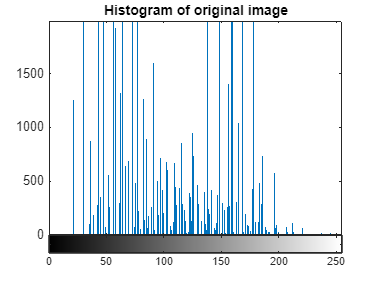


[counts, x] = imhist(I,256);
figure
imhist(I);
title('Histogram of original image')

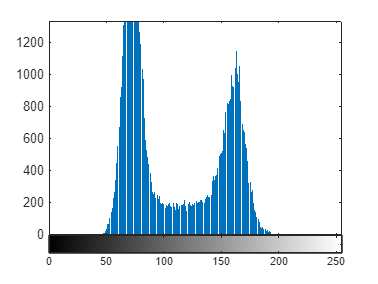

T = otsuthresh(counts);
I_otsu_bin = imbinarize(I, T);

I_f = uint8(mean_filt(I, 10));
[counts_f, x] = imhist(I_f,256);
figure
imhist(I_f);

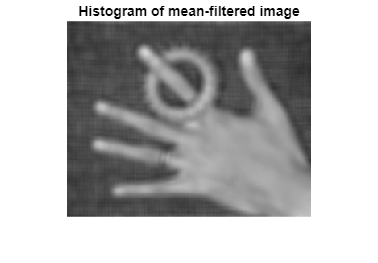

figure
imshow(I_f);
title('Histogram of mean-filtered image')

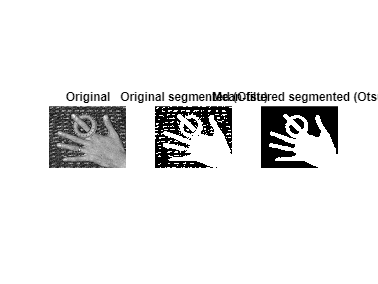

T_f = otsuthresh(counts_f);
I_f_otsu_bin = imbinarize(I_f, T_f);

figure
subplot(1,3,1)
imshow(I)
title('Original')
subplot(1,3,2)
imshow(I_otsu_bin)
title('Original segmented (Otsu)')
subplot(1,3,3)
imshow(I_f_otsu_bin)
title('Mean-filtered segmented (Otsu)')
axis off;



function I_f = mean_filt(I, w_size)
    [rows, cols] = size(I);
    padding = floor(w_size / 2);
    I_f = zeros(rows, cols);
    I_padded = padarray(I, [padding, padding], 'replicate', 'both');
    for i = 1:rows
        for j = 1:cols
            window = I_padded(i:i+w_size-1, j:j+w_size-1);
            window_mean = sum(window, 'all') / w_size^2;
            I_f(i, j) = window_mean;
        end
    end
end